Sesonality vibe, maybe try 24? 

clear
data=readtable("dataClean.csv")

data = 8760×12 table
           tstamp             AC      tou_id     DC     weekDay    Sat    Sun    wrkHr    dayTime    Off_Peak    Peak    Standard
    ____________________    ______    ______    ____    _______    ___    ___    _____    _______    ________    ____    ________

    01-Jan-2022 00:00:00    96.855      1       52.2       0        1      0       0         0          1         0         0    
    01-Jan-2022 01:00:00    97.053      1         52       0        1      0       0         0          1         0         0    
    01-Jan-2022 02:00:00    97.229      1       52

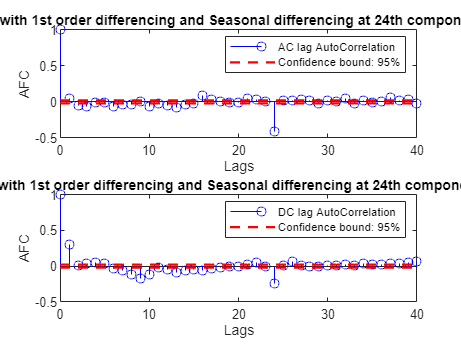





%First order differencing
ACdiff = array2table(diff(data.AC), "VariableNames","ACdiff");
DCdiff = array2table(diff(data.DC), "VariableNames","DCdiff");
data = [data(2:end,:) ACdiff DCdiff];


DC2diff = array2table(diff(data.DCdiff), "VariableNames","DC2diff");
data = [data(2:end,:) DC2diff];

slag = 24; %seasonal lag component
%Seasonal differencing
ACsdiffdiff = data.ACdiff(slag+1:end) - data.ACdiff(1:end-slag); 
ACsdiffdiff = array2table(ACsdiffdiff, "VariableNames","ACsdiffdiff");
DCsdiffdiff = data.DCdiff(slag+1:end) - data.DCdiff(1:end-slag);
DCsdiffdiff = array2table(DCsdiffdiff, "VariableNames","DCsdiffdiff");
data = [data(25:end,:) ACsdiffdiff DCsdiffdiff];



Lags = 40;
confidenceBound = 0.05;


[afcACsdiffdiff ,afcLags, bounds] = autocorr(data.ACsdiffdiff,NumLags = Lags, NumSTD=1.96);
figure;
subplot(2,1,1)
stem(afcLags,afcACsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title(' ACF with 1st order differencing and Seasonal differencing at 24th component - AC')


[afcDCsdiffdiff ,afcLags, bounds] = autocorr(data.DCsdiffdiff,NumLags = Lags, NumSTD=1.96);
subplot(2,1,2)
stem(afcLags,afcDCsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title('ACF with 1st order differencing and Seasonal differencing at 24th component - DC')

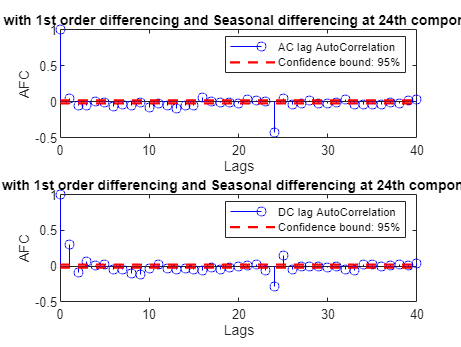



Lags = 40;
confidenceBound = 0.05;


[pafcACsdiffdiff ,afcLags, bounds] = parcorr(data.ACsdiffdiff,NumLags = Lags, NumSTD=1.96);
figure;
subplot(2,1,1)
stem(afcLags,pafcACsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("AC lag AutoCorrelation", "Confidence bound: 95%")
title(' PACF with 1st order differencing and Seasonal differencing at 24th component - AC')


[pafcDCsdiffdiff ,afcLags, bounds] = parcorr(data.DCsdiffdiff,NumLags = Lags, NumSTD=1.96);
subplot(2,1,2)
stem(afcLags,pafcDCsdiffdiff, "Marker","o","LineStyle","-","Color",'b');
hold on
plot(afcLags, repmat(bounds(1),length(afcLags )), 'r--' , "LineWidth",1.5);
plot(afcLags, repmat(bounds(2),length(afcLags) ), 'r--' , "LineWidth",1.5);
hold off
xlabel("Lags")
ylabel("AFC")
legend("DC lag AutoCorrelation", "Confidence bound: 95%")
title('PACF with 1st order differencing and Seasonal differencing at 24th component - DC')






[h, pValue, statistic, critValue] = kpsstest(data.ACsdiffdiff,ALpha = 0.05)

h = logical
   0


pValue = 0.1000

statistic = 6.0480e-04

critValue = 0.1460


[h, pValue, statistic, critValue] = kpsstest(data.DCsdiffdiff,ALpha = 0.05)

h = logical
   0


pValue = 0.1000

statistic = 0.0011

critValue = 0.1460

Time to build and test the model 

Gonna remove everything except the timeseries

data = removevars(data, [  "dayTime" "Off_Peak" "Peak" "Sat" "Standard" "Sun" "tou_id"  "wrkHr" "ACsdiffdiff" "DCsdiffdiff" "DC2diff" "tstamp" "weekDay"])

data = 8734×4 table
      AC       DC     ACdiff    DCdiff
    ______    ____    ______    ______

    98.829      50     0.551      0.3 
    97.729    49.7      -1.1     -0.3 
    97.881    49.7     0.152        0 
    98.799    49.3     0.918     -0.4 
    95.899    56.7      -2.9      7.4 
    97.098    71.6     1.199     14.9 
    97.083    70.2    -0.015     -1.4 
    96.893    71.5     -0.19      1.3 
    97.518    75.2     0.625      3.7 
    98.011    72.9     0.493     -2.3 
    97.676    71.3    -0.335     -1.6 
    96.949    69.5    -0.727     -1.8 
    97.615    68.6     0.666     -0.9 
    99.722    59.9     2.107     -8.7 
    98.033    46.8    -1.689    -13.1 
    96.846    46.4    -1.187     -0.4 



numObservations = size(data);
percentSplit = 0.7;

idxTrain = 1:floor(percentSplit*numObservations);
idxTest = floor(percentSplit*numObservations)+1:numObservations;
X = data(idxTrain,:);
T = data(idxTest,:);


%23%MAPE
%SARIMA = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1,'Seasonality',24,'SARLags',24,'SMALags',24,'Distribution','Gaussian');
%SARIMA = estimate(SARIMA,X.DCdiff,'Display','off')

%THE ONE I ACTUALLY USED!
SARIMA = arima('Constant',NaN,'D',0,'MALags',1:2,'Seasonality',24,'SARLags',24,'SMALags',24,'Distribution','Gaussian');
SARIMA = estimate(SARIMA,X.DC,'Display','off')

%SARIMA = arima('Constant',NaN,'D',0,'MALags',1,'ARLags',1,'Seasonality',24,'SARLags',24,'SMALags',[24, 48],'Distribution','Gaussian');
%SARIMA = estimate(SARIMA,X.DCdiff,'Display','off')

SARIMA =   arima with properties:

     Description: "ARIMA(1,0,1) Model Seasonally Integrated with Seasonal AR(24) and MA(48) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 49
               D: 0
               Q: 49
        Constant: -0.000123355
              AR: {0.0255785} at lag [1]
             SAR: {0.0459029} at lag [24]
              MA: {0.351889} at lag [1]
             SMA: {-0.710015 -0.22591} at lags [24 48]
     Seasonality: 24
            Beta: [1×0]
        Variance: 83.5775

Test Model

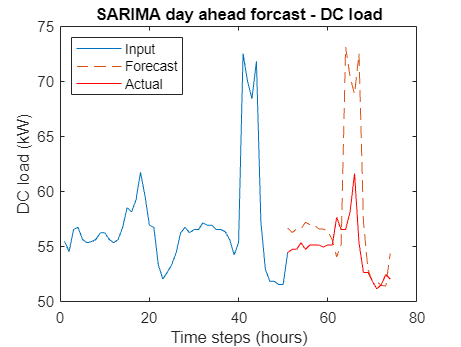

nForecast = 24;

offset = 51;
[Y, Ymse] = forecast(SARIMA, nForecast,T.DC(1:offset) ); %,'X0',[T.weekDay(1:offset) T.weekendDay(1:offset)] 

xAxis = 1:offset+nForecast-1;
figure
plot(1:offset,T.DC(1:offset))
hold on
plot(offset:offset+nForecast-1, Y,"--")
plot(offset:offset+nForecast-1, T.DC(offset:offset+nForecast-1),"r")
hold off

ylabel("DC load (kW)")
   xlabel("Time steps (hours)")
   title("SARIMA day ahead forcast - DC load")
legend("Input", "Forecast", "Actual", "Location","northwest")

timeStep=1;

for j = 1:(floor(length(T.DC(:))/timeStep)-ceil(24/timeStep)-76)

    offset = 76+j*timeStep;
    [Y, Ymse] = forecast(SARIMA, nForecast, T.DC(1:offset-1) );

    numTimeSteps = offset+nForecast-1;

    Ypred{j}(:) = Y;
    Yactual{j}(:) = T.DC(offset:numTimeSteps);
    Xactual{j}(:) = T.DC(offset-24:offset-1);
    YpredMse{j}(:) =Ymse;

    rmse(j) = mean((Y - T.DC(offset:numTimeSteps)).^2,"all");
    mape(j) = mean(abs(T.DC(offset:numTimeSteps)-Y)./T.DC(offset:numTimeSteps),"all")*100;
  
    mse(j,:)  = Ymse;
    rmsePerHr(j,:) = (Y - T.DC(offset:numTimeSteps)).^2;
    mapePerHr(j,:) =   (abs(T.DC(offset:numTimeSteps)-Y )./T.DC(offset:numTimeSteps)).*100;

    intRmse(j)  = ((trapz(Y)-trapz(T.DC(offset:numTimeSteps)))/24)^2;
    intTotalRmse(j)  = (trapz(Y)-trapz(T.DC(offset:numTimeSteps)))^2;
    intMape(j)  = (abs(trapz(Y) - trapz(T.DC(offset:numTimeSteps)))/(trapz(T.DC(offset:numTimeSteps))))*100;
end


% YmapeHr = zeros(24,1);
% Yrmse   = zeros(24,1);
% YseCal = zeros(24,1);
% 
% intMape2 = 0;
% intMape3 = 0;
% 
% rmse =0;
% for i=1:j
% Ymape{i}(:) = abs(Yactual{i} - Ypred{i})./(Yactual{i})*100;
% YmapeHr(:) = YmapeHr + Ymape{i}(:);
% 
% Yrmse(:) =  Yrmse(:)+YpredMse{i}(:);
% 
% YseCal(:) = YseCal(:) + (Yactual{i}(:) - Ypred{i}(:)).^2;
% 
% intMape3 = intMape3 + trapz(abs(Yactual{i}-Ypred{i}))/trapz(Yactual{i})*100;
% intMape2 = intMape2 + (abs(trapz(Yactual{i})-trapz(Ypred{i})))/trapz(Yactual{i})*100;
% 
% 
% end
% 
% 
% YmapeHr = YmapeHr./j
% YmapeMean = mean(YmapeHr)
% intMape3  = intMape3/j
% intMape2  = intMape2/j
% Yrmse   = sqrt(Yrmse./j)
% YrmseCal = sqrt(YseCal./j)
% YrmseCalMean = mean(YrmseCal)
% intRMSE = sqrt(intRMSE/(j*24))
% rmse = sqrt(rmse/j)

    DCintMape = mean(intMape)

DCintMape = 22.2208

    DCintRmse = sqrt(mean(intRmse))

DCintRmse = 19.3778

    DCtotalIntRmse = sqrt(mean(intTotalRmse))

DCtotalIntRmse = 465.0665

    DCrmseMean = sqrt(mean(rmsePerHr,"all"))

DCrmseMean = 28.9558

for i = 1:24

    hourlyDCrmse(i) = sqrt(mean(rmsePerHr(:,i),"all"));
   % hourlyDCrmse(i) = sqrt(mean(rmsePerHr(:,3,i),"all"));
    hourlyDCmape(i) = mean(mapePerHr(:,i),"all");
   % hourlyDCmape(i) = mean(mapePerHr(:,3,i),"all");
    givenRMSE(i)  = sqrt(mean(mse(:,i),'all'));
end


#### Save the DC Rmse and Mape

save('SARIMA_DC', 'hourlyDCmape','hourlyDCrmse','DCrmseMean','DCintMape','DCintRmse','DCtotalIntRmse')

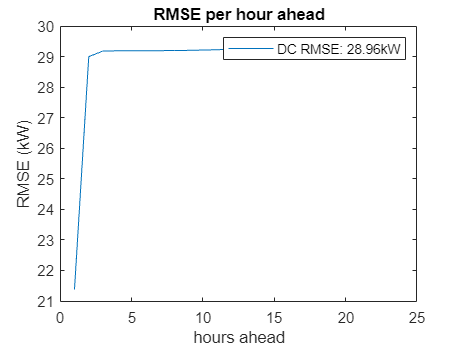

figure
plot(1:24, hourlyDCrmse);
hold on
%plot(1:24,hourlyDCrmse);
%plot(givenRMSE,"DisplayName","Given RMSE");
%plot(Yrmse)
%plot(YrmseCal)
hold off
legend( "DC RMSE: "+ round(DCrmseMean,2)+"kW")%"In loop Given", "out of loop Given" ,"out of loop Cal")%, "DC rmse: "+ sqrt(mean(rmse(:,3))))
title("RMSE per hour ahead")
xlabel("hours ahead")
ylabel("RMSE (kW)")

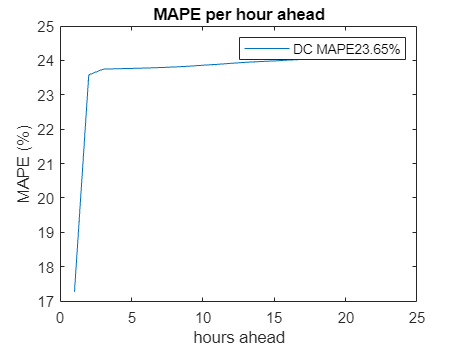

figure
plot(1:24, hourlyDCmape);
hold on
%plot(YmapeHr)
%plot(1:24,hourlyDCmape);
hold off
legend("DC MAPE" + round(mean(hourlyDCmape),2) +"%" )%, "DC mape: "+ mean(hourlyDCmape))
title("MAPE per hour ahead")
xlabel("hours ahead")
ylabel("MAPE (%)")




display("DC MAPE: " + mean(hourlyDCmape)+"%")

    "DC MAPE: 23.6464%"



display("DC RMSE: " + DCrmseMean+" kW")

    "DC RMSE: 28.9558 kW"

